## **LOAD THE IMAGE**

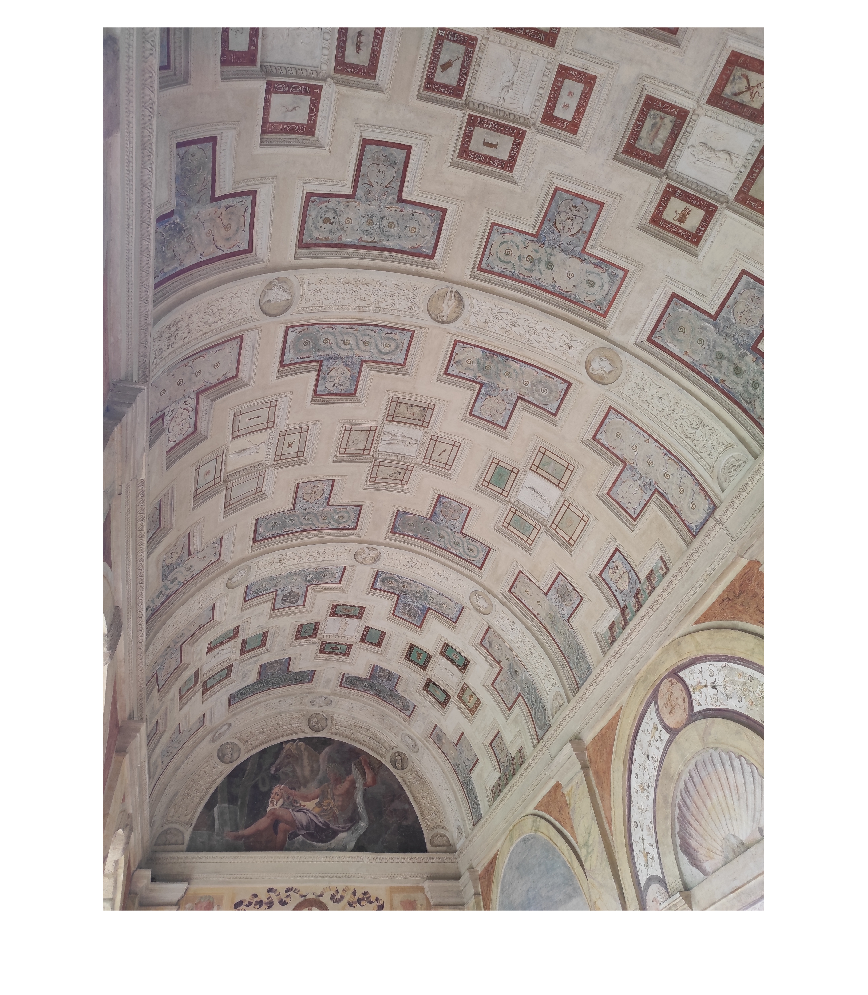

clear all;
im = imread('PalazzoTe.jpg');

%rotate the image
img=imrotate(im, -90);

%show the image
imshow(img);

## LOAD **NECESSARY GEOMETRIC ELEMENTS**

I=load('elements\CIRCULAR POINTS\I.mat').s1

I = 1.0e+03 *

   2.2498 - 4.0141i
   0.0644 - 1.1343i
   0.0010 + 0.0000i


J=load('elements\CIRCULAR POINTS\J.mat').s2

J = 1.0e+03 *

   2.2498 + 4.0141i
   0.0644 + 1.1343i
   0.0010 + 0.0000i



horizon=load('elements\LINES\horizon.mat').horizon

horizon =    -0.0005
    0.0018
    1.0000


V=load('elements\VANISHING POINTS\V.mat').V

V = 1.0e+03 *

    0.2115
    6.5958
    0.0010


## **SHAPE RECONSTRUCTION HOMOGRAPHY OF THE PLANE ORTHOGONAL TO THE CYLINDER AXIS**

#### **1) Recontruction of the Image of the conic dual to circular points**

im_DCP=I*J.'+J*I.';
im_DCP=im_DCP./norm(im_DCP);

#### 2) Decomposition of the latter to compute the Homograpgy for shape reconstruction

[U,D,v]=svd(im_DCP);

#### **3) Further decomposition to cancel out numerical errors and noise**

% To cancel out numerical errors
D(3,3)=1;
A=sqrt(D);

% Homographies
H=U*A

H =    -0.9757    0.0226   -0.0005
   -0.2189   -0.1007    0.0018
   -0.0001    0.0002    1.0000


Hsr=inv(H);

#### **4) Save the elements**

save('elements\HOMOGRAPHIES\VERTICAL PLANE\H.mat', 'H')
save('elements\HOMOGRAPHIES\VERTICAL PLANE\Hsr.mat' , 'Hsr')

Sanity check

DCP=[1,0,0; 
    0,1,0;
    0,0,0];

H*DCP * H.'

ans =     0.9526    0.2114    0.0001
    0.2114    0.0581    0.0000
    0.0001    0.0000    0.0000


im_DCP

im_DCP =     0.9526    0.2114    0.0001
    0.2114    0.0581    0.0000
    0.0001    0.0000    0.0000


## **COMPUTE THE CALIBRATION**

#### **1) Initialize the variables**

syms w1 w4 w5 w6

% variables
W=[w1 , 0 , w4;
    0 , 1 , w5;
    w4 , w5 , w6];

% homography
h1=H(:,1);
h2=H(:,2);
h3=H(:,3);


#### **2) Constraints using the homography H and the two circular points**

eqn1=h1.'* W * h2 == 0;
eqn2=h1.' * W *h1 - h2.'* W * h2 ==0;

#### **3) Constraints using V and the Axis**

M=cross(horizon,W*V);
% The latter provides 3 cosntraints but only 2 of them are
% linearly indipendent. We can select 2 among
% the 3 directions to set equal 0
% in this case I am selecting the components along x and along y
eqn3=M(1,1) ==0;
eqn4=M(2,1) ==0;

#### **4) Solve the system of equations**

eqns=[eqn1 , eqn2 , eqn3 , eqn4];
S=solve(eqns , [w1,w4,w5,w6]);

#### 5) Compute the image of the absolute conic omega

omega=double([S.w1 , 0 , S.w4;
    0 , 1, S.w5;
    S.w4 , S.w5 , S.w6])

omega = 1.0e+07 *

    0.0000         0   -0.0001
         0    0.0000   -0.0002
   -0.0001   -0.0002    1.7912


#### **6) Compute  the calibration matrix K**

% since skew =0 matrix K is an upper triangular matrix with
% element in row 1 column 2 =0

% matlab code for cholensky factorization find the 
% upper triangular matrix R that satisfy A=R.'*R
% Therfore in our case we first have to apply cholensky 
% to compute k^(-1) and then invert
K=inv(chol(omega));
K=K./K(3,3)

K = 1.0e+03 *

    3.3966         0    1.5527
         0    3.2321    2.2983
         0         0    0.0010



save('elements\CALIBRATION MATRIX\K.mat' , 'K')
